N=8;w1=2*pi/N;k=0:N-1;
x=[1,1,1,1];
x=[x,zeros(1,4)]

x =      1     1     1     1     0     0     0     0


[H]=freqz(x,1,w)

H =    4.0000 + 0.0000i   3.9989 - 0.0754i   3.9956 - 0.1507i   3.9901 - 0.2259i   3.9823 - 0.3008i   3.9724 - 0.3755i   3.9603 - 0.4498i   3.9461 - 0.5237i   3.9297 - 0.5971i   3.9111 - 0.6699i   3.8905 - 0.7421i   3.8677 - 0.8136i   3.8429 - 0.8844i   3.8161 - 0.9543i   3.7872 - 1.0233i   3.7564 - 1.0913i   3.7236 - 1.1584i   3.6889 - 1.2243i   3.6524 - 1.2891i   3.6140 - 1.3527i   3.5739 - 1.4150i   3.5320 - 1.4760i   3.4884 - 1.5356i   3.4431 - 1.5939i   3.3963 - 1.6506i   3.3479 - 1.7058i   3.2980 - 1.7595i   3.2466 - 1.8115i   3.1939 - 1.8619i   3.1398 - 1.9106i   3.0845 - 1.9575i   3.0280 - 2.0027i   2.9703 - 2.0460i   2.9115 - 2.0875i   2.8517 - 2.1271i   2.7909 - 2.1649i   2.7293 - 2.2007i   2.6668 - 2.2345i   2.6035 - 2.2664i   2.5395 - 2.2963i   2.4749 - 2.3241i   2.4098 - 2.3499i   2.3441 - 2.3737i   2.2780 - 2.3955i   2.2115 - 2.4151i   2.1448 - 2.4328i   2.0778 - 2.4483i   2.0107 - 2.4618i   1.9434 - 2.4732i   1.8762 - 2.4826i


magH=abs(H);phaH=angle(H);


X=dft(x,N);
magX=abs(X),phaX=angle(X)*180/pi

magX =     4.0000    2.6131    0.0000    1.0824    0.0000    1.0824    0.0000    2.6131


phaX =          0  -67.5000 -135.0000  -22.5000  -90.0000   22.5000  -45.0000   67.5000


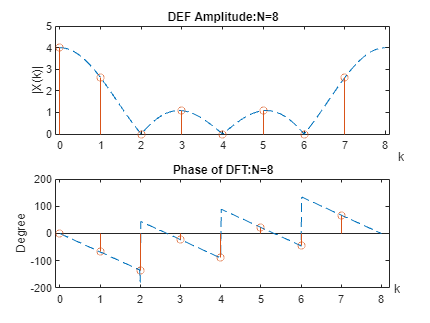

subplot(2,1,1);plot(w*N/(2*pi),magH,'--')
axis([-0.1,8.1,0,5]);hold on
stem(k,magX);
ylabel('|X(k)|');title('DEF Amplitude:N=8');text(8.3,-1,'k')
hold off
subplot(2,1,2);plot(w*N/(2*pi),phaH*180/pi,'--');
axis([-0.1,8.2,-200,200]);
hold on
stem(k,phaX)
ylabel('Degree');title('Phase of DFT:N=8');text(8.3,-200,'k')
hold off

N=16;w1=2*pi/N;k=0:N-1;
x=[1,1,1,1];
x=[x,zeros(1,12)]

x =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0


[H]=freqz(x,1,w)

H =    4.0000 + 0.0000i   3.9989 - 0.0754i   3.9956 - 0.1507i   3.9901 - 0.2259i   3.9823 - 0.3008i   3.9724 - 0.3755i   3.9603 - 0.4498i   3.9461 - 0.5237i   3.9297 - 0.5971i   3.9111 - 0.6699i   3.8905 - 0.7421i   3.8677 - 0.8136i   3.8429 - 0.8844i   3.8161 - 0.9543i   3.7872 - 1.0233i   3.7564 - 1.0913i   3.7236 - 1.1584i   3.6889 - 1.2243i   3.6524 - 1.2891i   3.6140 - 1.3527i   3.5739 - 1.4150i   3.5320 - 1.4760i   3.4884 - 1.5356i   3.4431 - 1.5939i   3.3963 - 1.6506i   3.3479 - 1.7058i   3.2980 - 1.7595i   3.2466 - 1.8115i   3.1939 - 1.8619i   3.1398 - 1.9106i   3.0845 - 1.9575i   3.0280 - 2.0027i   2.9703 - 2.0460i   2.9115 - 2.0875i   2.8517 - 2.1271i   2.7909 - 2.1649i   2.7293 - 2.2007i   2.6668 - 2.2345i   2.6035 - 2.2664i   2.5395 - 2.2963i   2.4749 - 2.3241i   2.4098 - 2.3499i   2.3441 - 2.3737i   2.2780 - 2.3955i   2.2115 - 2.4151i   2.1448 - 2.4328i   2.0778 - 2.4483i   2.0107 - 2.4618i   1.9434 - 2.4732i   1.8762 - 2.4826i


magH=abs(H);phaH=angle(H);
subplot(2,1,1);plot(w/pi,magH);grid
xlabel('');ylabel('|X|');title("DFT Amplitude :N=8");

X=dft(x,N);
magX=abs(X),phaX=angle(X)*180/pi

magX =     4.0000    3.6245    2.6131    1.2728    0.0000    0.8504    1.0824    0.7210    0.0000    0.7210    1.0824    0.8504    0.0000    1.2728    2.6131    3.6245


phaX =          0  -33.7500  -67.5000 -101.2500   45.0000   11.2500  -22.5000  -56.2500   90.0000   56.2500   22.5000  -11.2500  135.0000  101.2500   67.5000   33.7500


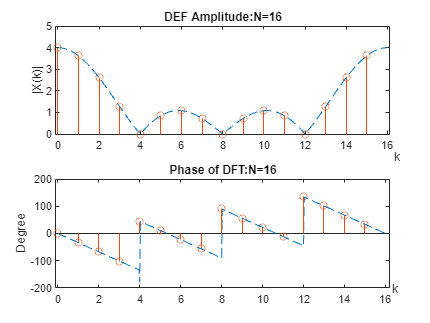

subplot(2,1,1);plot(w*N/(2*pi),magH,'--')
axis([-0.1,16.1,0,5]);hold on
stem(k,magX);
ylabel('|X(k)|');title('DEF Amplitude:N=16');text(16.3,-1,'k')
hold off
subplot(2,1,2);plot(w*N/(2*pi),phaH*180/pi,'--');
axis([-0.1,16.2,-200,200]);hold on
stem(k,phaX)
ylabel('Degree');title('Phase of DFT:N=16');text(16.3,-200,'k')
hold off